- Problem:

           A random variable $Z$is a sum of two R.V's $(X,Y)$, we may calculate the conditional expectaion of $X$, $E[x|z]$

**1. First :  The pdf of **$Z$

The pdf of $Z$ can be expressed as a convolution integral as 


$$f_Z(z)  = \int_{-\infty }^{\infty } f_X(x)f_Y (z-x) dx$$


Now in chebfun, there is a command to calculate  a convolution integral as "con"

for example  we may consider the sum of two  random variables $X, Y$ as


$$Z =X + Y$$


and corresponding pdf of $X,Y$which are independent, 


$$f_X(x)=\begin{cases}
    1/2 & \text{if   0<x<2 }.\\
    0, & \text{otherwise}.
  \end{cases}
$$


and


$$f_Y (y)=\begin{cases}
    1 & \text{if $  -1/2<x<1/2 $}.\\
    0, & \text{otherwise}.
  \end{cases}
$$


Then the  pdf of $Z$ is

                                                $f_Z(z)  = \int_{-\infty }^{\infty} f_X(x)f_Y (z -x)
 dx $,

To draw the plot of pdf of $Z$is 

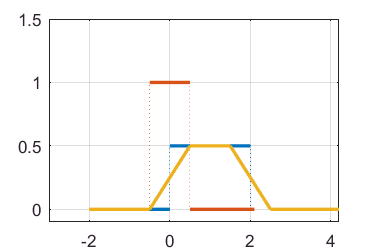


LW = 'linewidth';
fx = chebfun({@(x) 0 1/2 0},[-1 0 2 2.1]);
fy = chebfun({@(x) 0 1 0},[ -1 -1/2 1/2 2.1]);
figure('Position', [10 10 300 200])
plot(fx,LW,2); grid on; hold on
axis([-3 3 -0.1 1.5])
plot(fy,LW,2);
fz = conv(fx,fy);
plot(fz, LW,2)

% hold off

Here $f_Z (z) \ne 0$ is in the range of $-0.5 \le  z \le 2.5 $ as expected in the range $(x,y)$. 

**2. Second we may see the conditional pdf  **$f(x|z)$**. **

 **2.1 In the material in Tutorial, **

 1) $-1/2 \lt z \lt 1/2$


$$f_{X|Z} (x|z)=\begin{cases}
     \frac{1}{z+1/2} & x \in [0, .z+1/2]\\
    0, & \text{otherwise}.
  \end{cases}
$$


2) $1/2 \lt z \lt 3/2 $


$$f_{X|Z} (x|z)=\begin{cases}
    1 & x \in [z-1/2 , .z+1/2]\\
    0, & \text{otherwise}.
  \end{cases}
$$


3) $3/2 \lt z \lt 5/2$


$$f_{X|Z} (x|z)=\begin{cases}
    \frac{1}{5/2-z}& x \in [z-1/2 , .2]\\
    0, & \text{otherwise}.
  \end{cases}
$$


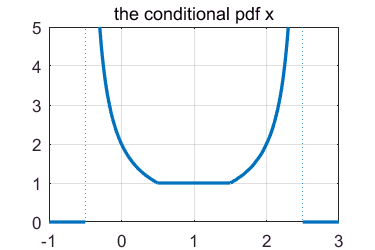

clear all; clf
LW ='linewidth';
fx_z = chebfun({0,@(z)1/(z+1/2), 1, @(z) 1/(5/2 -z),0 },[-1 -1/2 1/2 3/2 5/2 3],'splitting', 'on');
figure('Position', [10 10 300 200])
plot(fx_z,LW,2); grid on
axis([-1 3 0 5])
title('the conditional pdf x')

 **2.2 Check the legitimacy**

So far we get the conditional pdf in the different cases. However, is it a legal pdf?  We know for any pdf $g(x)$

should satisfy


$$\int_{-\infty }^{\infty} g(x)dx = 1$$


So let us check this condition. For $z =0$, then 


$$f(x |z =0)  = \frac{1}{1/2
 + z} |_{z=0} = 2  \ x \in [0 \ 1/2]$$


which yield to 


$$\int_{0}^{1/2} 2dx = 1$$


What is the case of z =1  and 2?

**2.3 Some remarks**

Here some strange things are happened. at the boundary i.e., $z = -0.5 \ and \ 2.5 $, the $f(x|z)  --> \infty$. Hence  if You measure $z =-0.5$, then the only case is 


$$x = 0 \ and \  y = -0.5$$
 

and vice versa when , **which implies **$x= 0$** in pobability 1! . What is the value of the conditional pdf at these points? Hence in order to be "1" at these point, the value of pdf should be infinite!**

**3. Finally the conditional expectation;**

Now we are ready to calculate the conditional expectation. First we may calculate the unconditional expectaion and it's variance. 

**3.1 The unconditional expectation and its variance**

By the definition, the unconditional expectation is 


$$E[x] = \int _{-\infty}^{\infty} xf(x)dx$$



$$=\int_{0}^{2} x(1/2) dx = 1/2 \int_{0}^{2}xdx = 1$$


and its variance is 


$$E[x -E[x]]^2  = \int_{0}^{2}(x-1)^2(1/2) dx=1/3$$


**3.2 The conditional Expectastion and the variance : the minimum variance estimator **

  In my material, 

1) For $z \in [-1/2 \ 1/2]$


$$E[x|z] = \int_{0}^{z+1/2} xf(x|z) dx =  \frac{1}{2} (z + \frac{1}{2})$$



$$E[(x-E[x|z])^2 ] |z] =\frac{1}{12} (z + \frac{1}{2})^2$$


2) For $z \in [1/2 ,\ 3/2]$


$$E[x|z] =z$$



$$E[(x-E[x|z])^2 ] |z] =\frac{1}{12} $$


3)For $z \in [\frac{3}{2}, \ \frac{5}{2}]$


$$E[x|z] =\frac{1}{2}(z +\frac{3}{2})$$



$$E[(x-E[x|z])^2 ] |z] =\frac{1}{12} (\frac{5}{2}-z)^2$$


Since in  my material, there is a graph for $E[x|z]$, i will draw the variance 

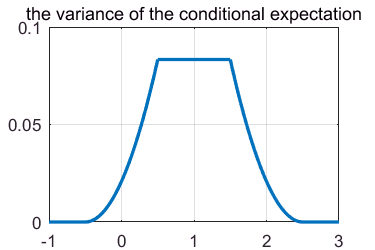

clear all; clf
LW ='linewidth';
var_xz = chebfun({0,@(z) (z+1/2)^2/12 , 1/12, @(z) (5/2-z)^2/12,0},[-1 -1/2 1/2 3/2 5/2 3],...
    'splitting', 'on');
figure('Position', [10 10 300 200])
plot(var_xz, LW,2); grid on
title('the variance of the conditional expectation')

**3.3 Some remarks **

What have we done unitl now?  

 -. Find the uncondtional expectation $E[x]$ , and its variance = 1/3 

 -. Find the conditional expectation $E[x|z]$  and its variance in the previous figure, 

Which one is better estimator? Look at the variance, for all $z$

    
$$\sigma^2 (x|z) < \sigma ^2 (x)$$
 